addpath(genpath('..'));
clear all
close all

[data_points1, size] = parseSection('3dFab_1.txt');
[data_points2] = parseSection('3dFab_2.txt');

% Determine Fourier coefficients for each data_point
fs_order = 6;

data_point_obj1 = data_points1(1);    
data_point_obj1 = data_point_obj1.Normalize; 
data_point_obj1 = data_point_obj1.GenerateFourier(fs_order);
data_point_obj1 = data_point_obj1.GenerateTensors;
data_point_obj1 = data_point_obj1.ComputeStats;


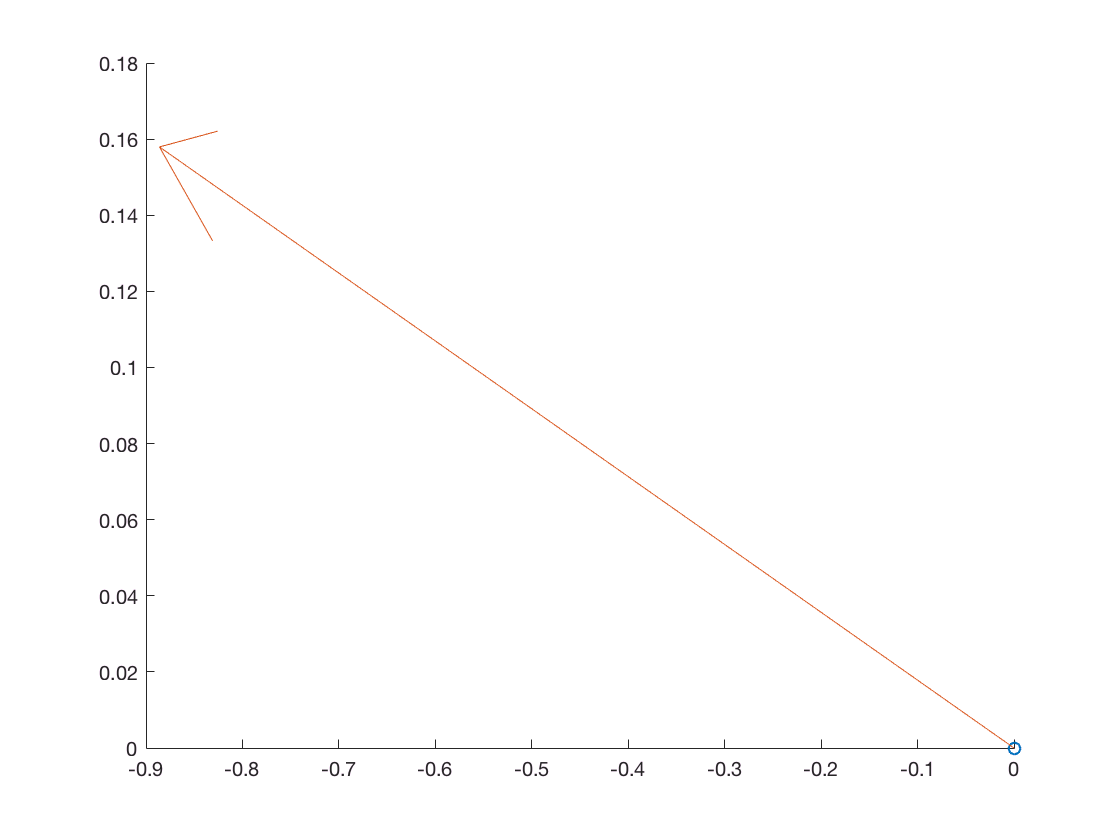

figure
hold on
scatter([data_point_obj1.x],[data_point_obj1.y])
u1=cos([data_point_obj1.mean_odf]);
v1=sin([data_point_obj1.mean_odf]);
quiver([data_point_obj1.x],[data_point_obj1.y], u1,v1)
hold off

theta = 90*pi/180;
T = [cos(theta) sin(theta) 0;
    -sin(theta) cos(theta) 1;
    0 0 1];

% [Ts, imageSize] = loadMatrices();
% T = translateMatrices(data_points1, Ts{1}, imageSize(1,:));

%Flip to fiji coordinates
YRangemm = max([data_point_obj1.y]) - min([data_point_obj1.y]);
% Y = [data_point_obj1.y];
% Y = Y - YRangemm; 
% Y = Y*(-1);


% data_point_obj1.y = Y;
data_point_obj2 = data_point_obj1.ApplyTransformation(T);
data_point_obj2 = data_point_obj2.ComputeStats();
% 
% Y1 = [data_point_obj1.y];
% Y2 = [data_point_obj2.y];
% 
% data_points_obj1.y = Y1*(-1) + YRangemm;
% data_points_obj2.y = Y2*(-1) + YRangemm;

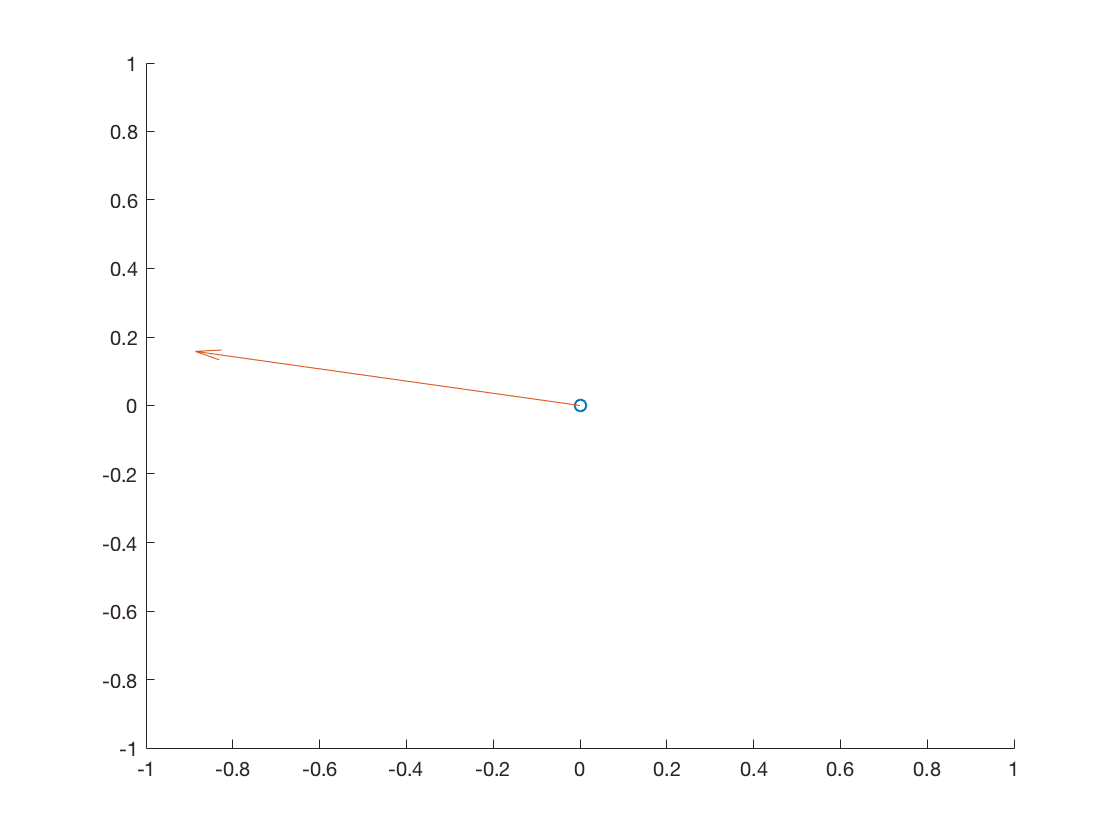

figure
hold on
scatter([data_point_obj1.x],[data_point_obj1.y])
u1=cos(data_point_obj1.mean_odf);
v1=sin(data_point_obj1.mean_odf);
quiver(data_point_obj1.x,data_point_obj1.y, u1,v1)
axis([data_point_obj1.x-1 data_point_obj1.x+1 data_point_obj1.y-1 data_point_obj1.y+1])

hold off

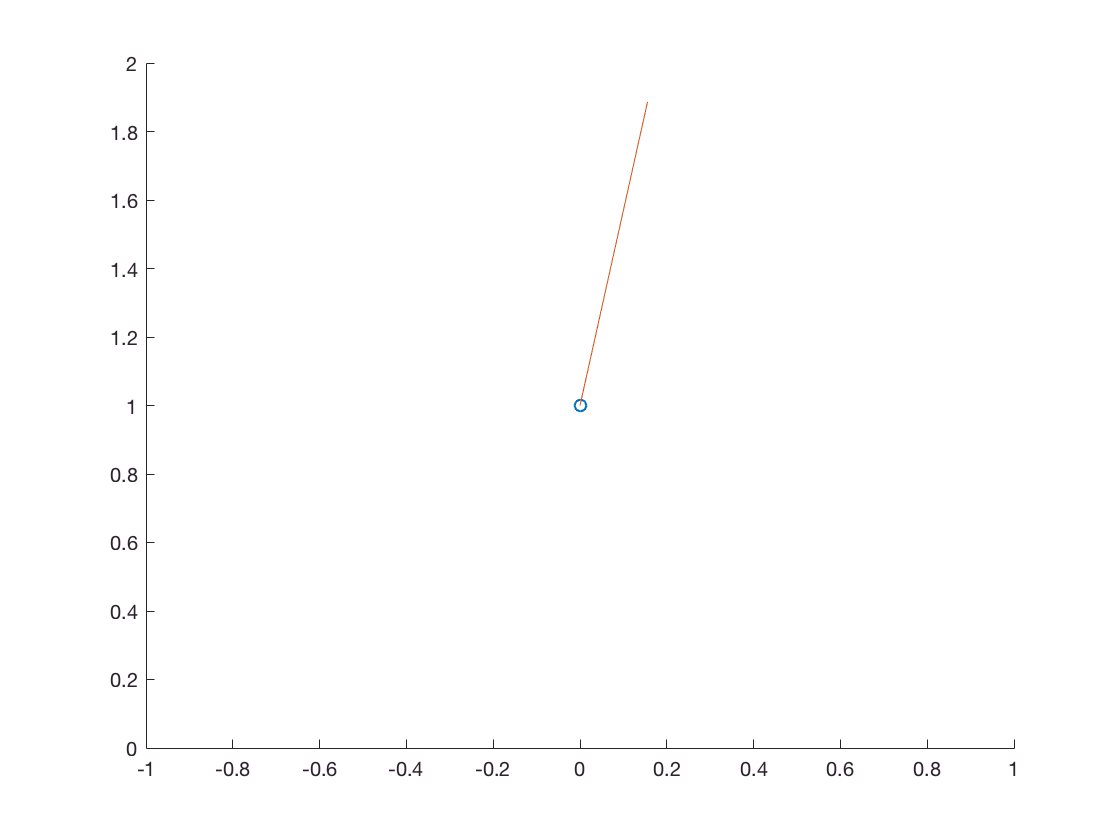


figure
hold on
scatter([data_point_obj2.x],[data_point_obj2.y])
u2=cos([data_point_obj2.mean_odf]);
v2=sin([data_point_obj2.mean_odf]);
quiver([data_point_obj2.x],[data_point_obj2.y], u2,v2,'.')
axis([data_point_obj2.x-1 data_point_obj2.x+1 data_point_obj2.y-1 data_point_obj2.y+1])

hold off